# Center Figure Snapshot on a Page

This example shows how to center a figure snapshot on a landscape page for PDF and Microsoft® Word reports.

The example creates a Report API report having landscape layout, creates MATLAB figures, and then uses the `centerFigure` local function to create and add the snapshots of these figures at the center of the page.

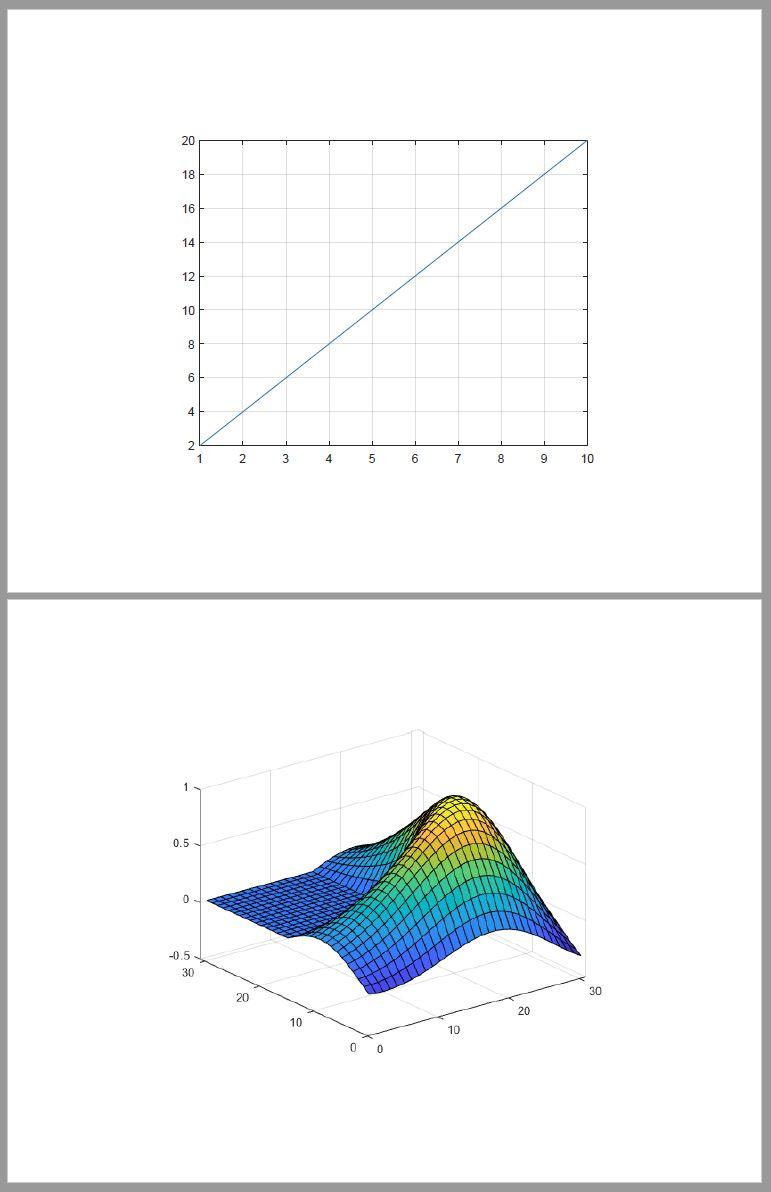

## Create Report

Import the DOM and Report API packages so that you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*
import mlreportgen.report.*

Create a PDF report. To create a Microsoft® Word report, change `"pdf" `to `"docx"`.

rpt = Report("myreport","pdf");
open(rpt);

## Update Report Page Layout

Create a page layout object.

if strcmpi(rpt.Type,"pdf")
    pageLayoutObj = PDFPageLayout;
else
    pageLayoutObj = DOCXPageLayout;
end

Specify the page orientation, height, and width.

pageLayoutObj.PageSize.Orientation = "landscape";
pageLayoutObj.PageSize.Height = "8.5in";
pageLayoutObj.PageSize.Width = "11in";

Specify the page margins.

pageLayoutObj.PageMargins.Top = "0.5in";
pageLayoutObj.PageMargins.Bottom = "0.5in";
pageLayoutObj.PageMargins.Left = "0.5in";
pageLayoutObj.PageMargins.Right = "0.5in";

pageLayoutObj.PageMargins.Header = "0.3in";
pageLayoutObj.PageMargins.Footer = "0.3in";

Add the page layout object to the report.

add(rpt,pageLayoutObj);

## Create and Add Figures

Create a figure with a linear plot.

f = figure();
plot(1:1:10,2:2:20);
grid on;

Call the `centerFigure` local function to add the figure snapshot at the center of the page. Then, delete the figure object.

centerFigure(f,rpt);
delete(f);

Similarly, add the membrane surface plot snapshot at the center of the page.

centerFigure(surf(membrane),rpt);
delete(gcf);

## Generate the Report

Close and view the report.

close(rpt);
rptview(rpt);

## The `centerFigure` Local Function

This function creates a snapshot of the specified figure and adds it at the center of the page in the specified report. The function uses the Report API `Figure` reporter to take the figure snapshot and an invisible DOM `Table` to do the layout.

function centerFigure(figure,rpt)

Import the DOM API, Report API, and report generator utility packages so that you do not have to use long, fully-qualified class names.

    import mlreportgen.dom.*
    import mlreportgen.report.*
    import mlreportgen.utils.*

Get the report's current page layout to determine the current page size and the page margins. The page layout information is used to calculate the page body size in order to size the layout table created in a subsequent step.

    pageLayout = getReportLayout(rpt);
    pageSize = pageLayout.PageSize;
    pageMargins = pageLayout.PageMargins;

Calculate the page body width. The page body width denotes the page width available for the content and is determined by subtracting the left and right margin size from the page width. For DOCX output, gutter size also needs to be subtracted.

    bodyWidth = units.toInches(pageSize.Width) - ...
        units.toInches(pageMargins.Left) - ...
        units.toInches(pageMargins.Right);
    
    if strcmpi(rpt.Type,"docx")
        bodyWidth = bodyWidth - ...
            units.toInches(pageMargins.Gutter);
    end
    bodyWidth = sprintf("%0.2fin",bodyWidth);

Calculate the page body height. The page body height denotes the page height available for the content and is determined by subtracting the top and bottom margin size from the page height. For PDF output, the header and footer sizes also need to be subtracted because the body extends from the bottom of the header to the top of the footer.

    bodyHeight = units.toInches(pageSize.Height) - ...
        units.toInches(pageMargins.Top) - ...
        units.toInches(pageMargins.Bottom);
    
    if strcmpi(rpt.Type,"pdf")
        bodyHeight = bodyHeight - ...
            units.toInches(pageMargins.Header) - ...
            units.toInches(pageMargins.Footer);
    end
    bodyHeight = sprintf("%0.2fin",bodyHeight);

Create a `Figure` object for the specified figure. Then, create an `Image` object wrapped around the figure snapshot image file. Scale the image to fit the entry of the layout table created in a subsequent step.

    fig = Figure(figure);
    figImg = Image(getSnapshotImage(fig,rpt));
    figImg.Style = [figImg.Style {ScaleToFit}];

Wrap the image in a paragraph because PDF requires that an image reside in a paragraph. Update the paragraph style to make sure that there is no white space around the image.

    para = Paragraph(figImg);
    para.Style = [para.Style {OuterMargin("0in","0in","0in","0in")}];

Add the paragraph that contains the figure snapshot in a 1-by-1 invisible layout table (`lo_table`). A table is considered invisible when the borders are not defined for the table and its table entries.

    lo_table = Table({para});

Span the table to the available page body width.

    lo_table.Width = bodyWidth;

Span the only table entry to the available page body height. Also, specify the vertical and horizontal alignment formats to make sure that the image is centered both vertically and horizontally inside the table entry.

    lo_table.TableEntriesStyle = [lo_table.TableEntriesStyle ...
        { ...
        Height(bodyHeight), ...
        HAlign("center"), ...
        VAlign("middle") ...
        }];

Add the layout table to the report.

    add(rpt,lo_table);
end

*Copyright 2019 The MathWorks, Inc.*